
servoAngleFeedBack=1; calibServo=0.7 %0.7

calibServo = 0.7000

stepYaw=1;      yawStepSize=10;
stepRoll=1;
stepPitch=1;    pitchStepSize=5;
stepServo=0;    servoStepSize=deg2rad(10);
rightDeadBandWidthDeg=0;%10;
leftDeadBandWidthDeg=0;%15;
noiseOn=0;
servoTimesSlower=200;%makes the servo's x times slower;Defualt=1;
batteryPositionOffset=-2/100; %in meters


model='Drone_2M_sim_V7_blackBox'

model = 'Drone_2M_sim_V7_blackBox'

SIM_TIME=45;
simout=sim(model,SIM_TIME);

Error due to multiple causes.

Caused by:
    Error using blackBoxFromModel
    Error evaluating parameter 'Mass' in 'Drone_2M_sim_V7_blackBox/Motors/Motor Left/Cylindrical Solid'
        Error using blackBoxFromModel
        Unrecognized function or variable 'propellerMass'.
            Error using blackBoxFromModel
            Variable 'propellerMass' has been deleted fro

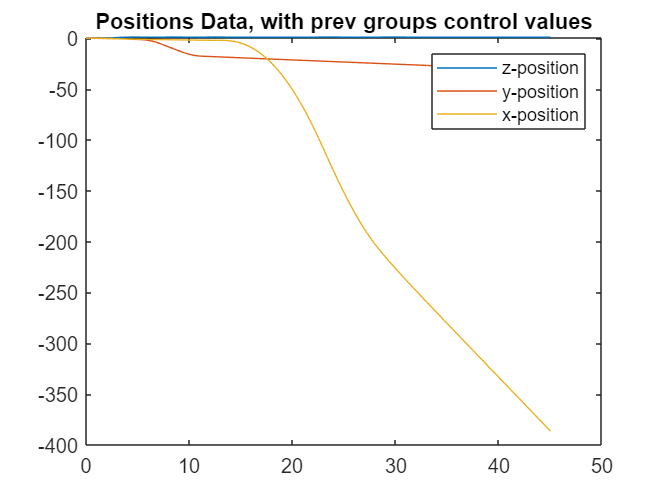

%plotting position data
clf
positionData=simout.logsout.getElement("Position").Values.Data;
t=simout.logsout.getElement("Position").Values.Time;
plot(t,positionData)
title("Positions Data, with prev groups control values")
legend("z-position","y-position","x-position")


%height
heightData=simout.logsout.getElement("height pos").Values.Data;
uheightData=simout.logsout.getElement("heightCtrl_u").Values.Data;
heightRefData=simout.logsout.getElement("height ref").Values.Data;
plot(t,[heightData,heightRefData])
title("height pos simulation")
legend("height pos","height pos ref","height mixer")

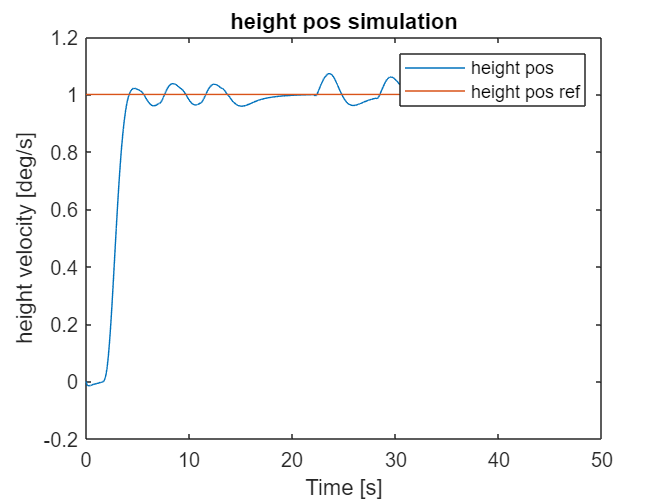

xlabel('Time [s]');
ylabel('height velocity [deg/s]')


%yaw
uYawData=simout.logsout.getElement("u-yaw").Values.Data;
yawData=simout.logsout.getElement("yaw vel").Values.Data;
yawRefData=simout.logsout.getElement("yaw vel ref").Values.Data;
plot(t,[yawData,yawRefData])
title("Yaw velocity simulation")
legend("Yaw velocity","Yaw velocity ref","Yaw mixer")

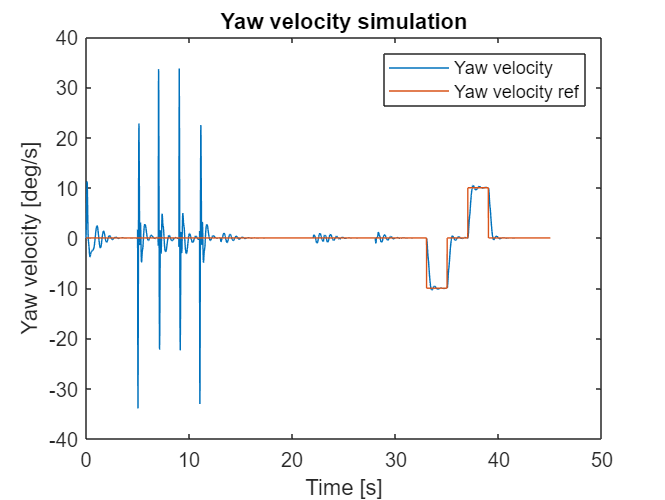

xlabel('Time [s]');
ylabel('Yaw velocity [deg/s]')
ylim([-40 40])

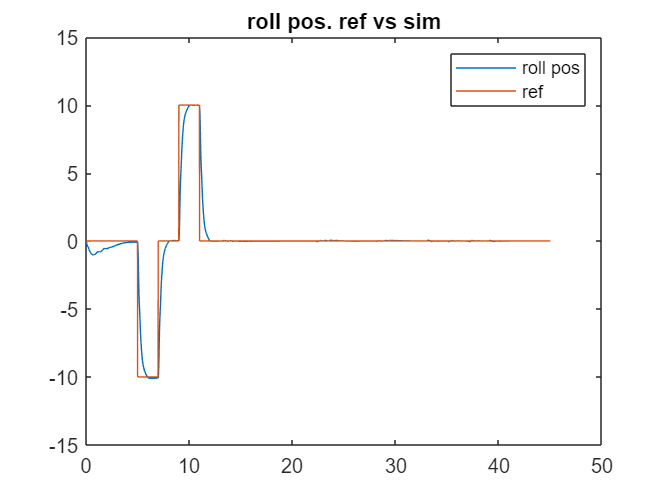

%integratoren gør det værre
%mixer skal gå op til 400

%roll
rollData=simout.logsout.getElement("roll deg").Values.Data;
urollData=simout.logsout.getElement("u-roll").Values.Data;
rollRefData=simout.logsout.getElement("roll deg ref").Values.Data;
plot(t,[rollData,rollRefData])
title("roll pos. ref vs sim")
legend("roll pos","ref")

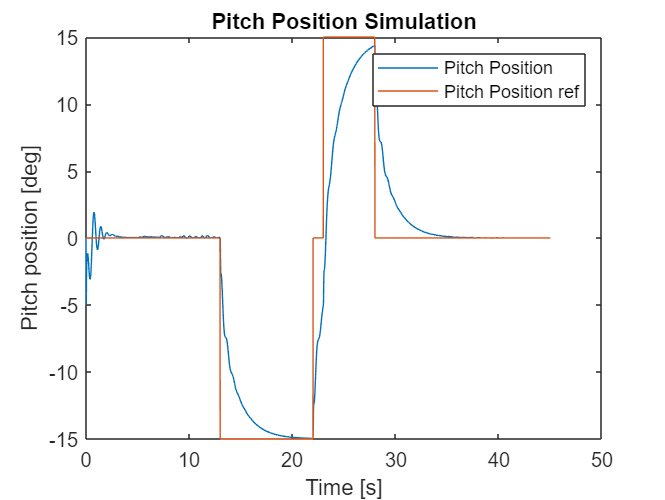



%pitch
pitchData=simout.logsout.getElement("pitch deg").Values.Data;
%pitchData=simout.logsout.getElement("servoDeg").Values.Data;
pitchData=simout.logsout.getElement("servoToGround").Values.Data;
upitchData=simout.logsout.getElement("u-pitch").Values.Data;
pitchRefData=simout.logsout.getElement("pitch deg ref").Values.Data;
plot(t,[pitchData,pitchRefData])
legend("Pitch Position","Pitch Position ref")
title("Pitch Position Simulation")
xlabel('Time [s]');
ylabel('Pitch position [deg]') 

%save("pitchStep15.mat","pitchData","pitchTime")
%ylim([-20 25])
%+-300 mixer

%black box model:

time=simout.logsout.getElement("roll sampled").Values.Time

time =          0
    0.0010
    0.0020
    0.0030
    0.0040
    0.0050
    0.0060
    0.0070
    0.0080
    0.0090


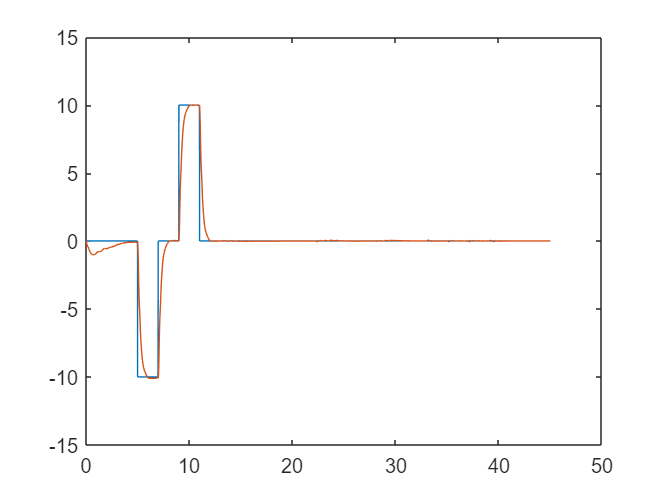

rollData=simout.logsout.getElement("roll sampled").Values.Data;
plot(time,rollData)

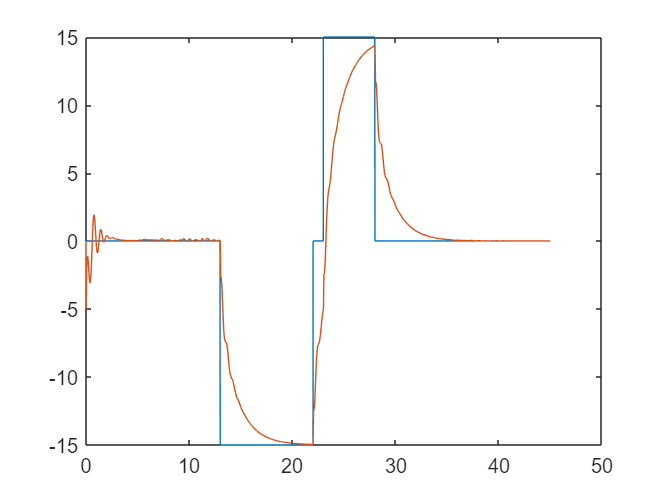

pitchData=simout.logsout.getElement("pitch sampled").Values.Data;
plot(time,pitchData)

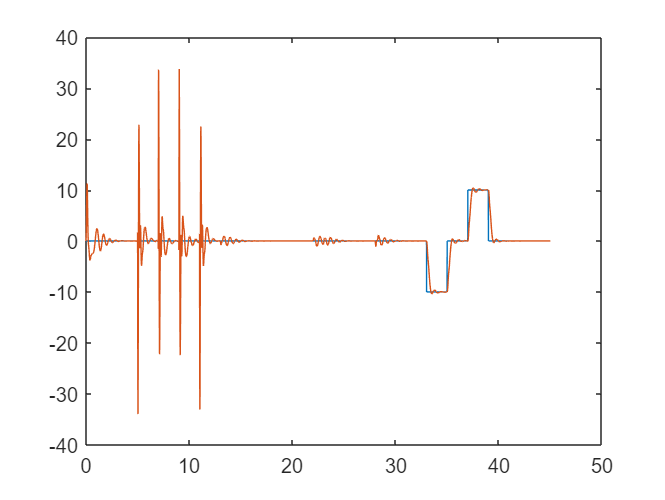

yawData=simout.logsout.getElement("yaw sampled").Values.Data;
plot(time,yawData)

input=[rollData(:,1),pitchData(:,1),yawData(:,1)]

input =      0     0     0
     0     0     0
     0     0     0
     0     0     0
     0     0     0
     0     0     0
     0     0     0
     0     0     0
     0     0     0
     0     0     0


output=[rollData(:,2),pitchData(:,2),yawData(:,2)]

output =          0         0         0
    0.0000   -0.0824    0.0066
    0.0000   -0.2685    0.0448
    0.0000   -0.5106    0.0924
    0.0000   -0.7879    0.1433
    0.0000   -1.0882    0.1958
   -0.0000   -1.4030    0.2491
   -0.0001   -1.7256    0.3033
   -0.0003   -2.0499    0.3582
   -0.0004   -2.3705    0.4139


input2=input(time>4,:)

input2 =      0     0     0
     0     0     0
     0     0     0
     0     0     0
     0     0     0
     0     0     0
     0     0     0
     0     0     0
     0     0     0
     0     0     0


output2=output(time>4,:)

output2 =    -0.1080    0.0301    0.0098
   -0.1079    0.0300    0.0099
   -0.1079    0.0300    0.0101
   -0.1078    0.0299    0.0102
   -0.1077    0.0299    0.0103
   -0.1076    0.0298    0.0105
   -0.1076    0.0298    0.0106
   -0.1075    0.0297    0.0107
   -0.1074    0.0297    0.0108
   -0.1073    0.0296    0.0109


%save("stepNewCtr.mat","output","time")

                                                                                  
%ss9u
%save('stateSpaceNulSlør','ss9u')
%ss9u er også bedst for slør

load('stateSpaceNulSlør') %load ss model
ss9u

ss9u =
  Continuous-time identified state-space model:
      dx/dt = A x(t) + B u(t) + K e(t)
       y(t) = C x(t) + D u(t) + e(t)
 
  A = 
             x1        x2        x3        x4        x5        x6        x7        x8        x9
   x1    -3.033    -0.654     1.725    0.1191    0.5094    0.3258  -0.02352  -0.01085  -0.06111
   x2    -1.028    -1.691    0.3605    0.2608    -1.299    -0.743  0.005532   0.03459   0.07552
   x3    -14.29     -6.18    -13.86     10.56     -9.07     8.673    -2.789    0.1071     2.454
   x4    -10.67    -5.365    -33.96    -10.35     -1.53    0.5395     28.58    -1.165    0.3697
   x5   -0.2675    -2.559      6.35    -2.752    -21.78    -18.83     7.469    -3.617     84.62
   x6   -0.7415    -3.606    -13.21    -4.369    -23.78    -16.72     -17.7    -13.68    -80.98
   x7    -70.88    -32.09    -152.9    -161.3     -8.92    -1.551    -419.3    -223.8     175.7
   x8    -33.64    -14.05    -73.08    -59.81     3.312    -4.015    -166.1    -90.67     16

H=tf(ss9u)

H =
 
  From input "u1" to output...
                                                                                                                                  
         -0.2651 s^8 + 117.5 s^7 + 1.666e04 s^6 + 2.524e07 s^5 + 1.881e09 s^4 + 1.06e11 s^3 + 3.216e12 s^2 + 1.517e13 s + 1.293e13
                                                                                                                                  
   y1:  ----------------------------------------------------------------------------------------------------------------------------
                                                                                                                                    
        s^9 + 1222 s^8 + 2.257e05 s^7 + 3.176e07 s^6 + 1.672e09 s^5 + 4.888e10 s^4 + 1.04e12 s^3 + 7.123e12 s^2 + 1.835e13 s        
                                                                                                                                    
                                      

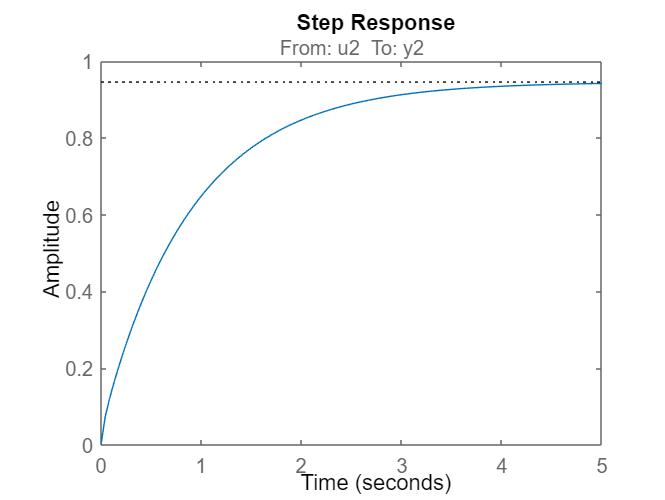

step(H(2,2))

%test
syms t
func(t)=piecewise(t>=0 & t<5,sin(t*10)*2,...
    t>=5 & t<10,sin(t*10)*2+t-5,...
    t>=10 & t<=15,sin(t*10)*2+5)

$$func(t) = \left\{ \begin{array}{cl} 2\,\sin\left(10\,t\right) & \text{ if }t\in \left[0,5\right)\\ t+2\,\sin\left(10\,t\right)-5 & \text{ if }t\in \left[5,10\right)\\ 2\,\sin\left(10\,t\right)+5 & \text{ if }t\in \left[10,15\right] \end{array}\right.$$

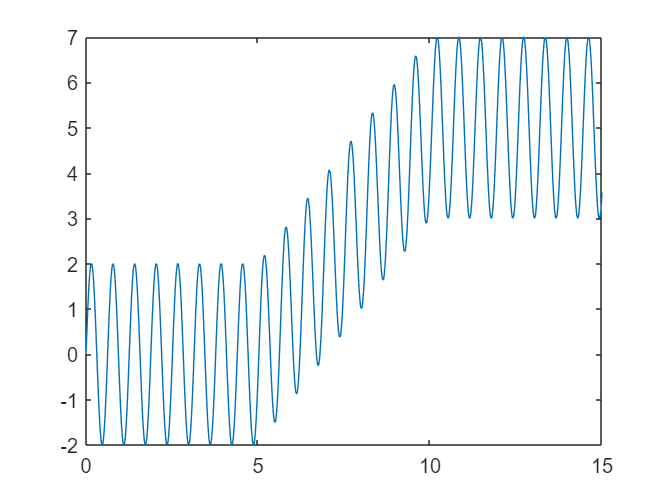

fplot(func(t),[0 15])

tsam=(0:0.01:15)'

tsam =          0
    0.0100
    0.0200
    0.0300
    0.0400
    0.0500
    0.0600
    0.0700
    0.0800
    0.0900


funcRef(t)=piecewise(t>=0 & t<5,0,...
    t>=5 & t<10,t-5,...
    t>=10 & t<=15,5)

$$funcRef(t) = \left\{ \begin{array}{cl} 0 & \text{ if }t\in \left[0,5\right)\\ t-5 & \text{ if }t\in \left[5,10\right)\\ 5 & \text{ if }t\in \left[10,15\right] \end{array}\right.$$

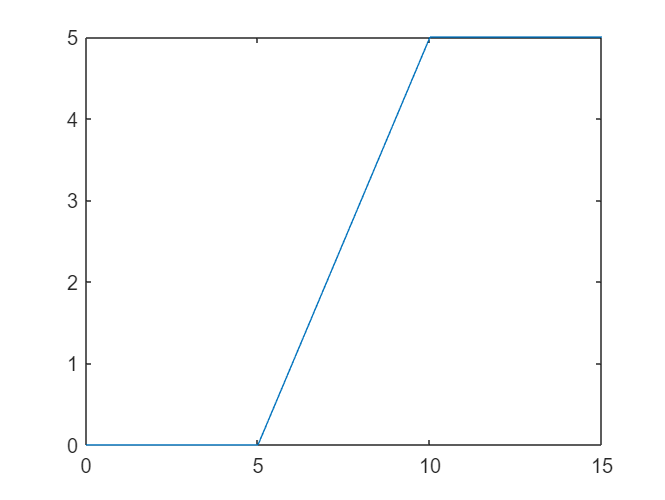

fplot(funcRef(t),[0 15])

inputTest=eval(vpa(funcRef(tsam)))

inputTest =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0


outputTest=eval(vpa(func(tsam)))

outputTest =          0
    0.1997
    0.3973
    0.5910
    0.7788
    0.9589
    1.1293
    1.2884
    1.4347
    1.5667


ss9

Unrecognized function or variable 'ss9'.

H=tf(ss9)
step(H(2,2))
syms t s
T=0.6
f=1/T
sineLa=laplace(sin(t*2*pi*f)*2,t,s)
[num,denum]=numden(sineLa)
num=sym2poly(num)
denum=sym2poly(denum)
sineTF=tf(num,denum)
step(H(2,2)*15+sineTF*4)


clf
output3=output(time>15,1)
plot(time(1:length(output3)),output3)
hold on
fplot(sin(t*2*pi*f)*2,[0 30])